# Numerical Frequency Test

This live-script features the following:

- 2D example

- construct acoustic sources via functions

- setup to run basic acoustic solver

- different visualizations

- plot for medium parameters

- animate for solutions

- animateMedBack for solutions

- plotTimeSeries for solutions

Acoustic equations: 


$$\frac{\partial p}{\partial t} + \kappa \left( \frac{\partial v_x}{\partial x}  + \frac{\partial v_y}{\partial y}\right)= f_p$$



$$\frac{\partial v_x}{\partial t} + \beta \frac{\partial p}{\partial x} = f_{v_x}$$



$$\frac{\partial v_y}{\partial t} + \beta \frac{\partial p}{\partial y} = f_{v_y}$$


assuming zero-pressure at boundaries, and initial conditions provided by user.

## Week 6-7 implementations:

- Includes square grid, $ h = \Delta x = \Delta y$, where h is the grid spacing between each point.

h is computed to satisfy a desired range of points per wavelength. 

The computational spatial grid is defined and used to initialize the grid space for the pressure fields.

clear

N_lambda = 16; %desired points per wavelength

CFL_factor = 0.9;

% medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
kappa_val = 1;
beta_val = 1;
c = sqrt(kappa_val*beta_val);

%Length of grid space for choice of square grid, change to L maybe?
Lx = 1;
Ly = Lx;
Lt = 1;
%make sure time is ten periods 
domain_x = [0,Lx];
domain_y = [0,Ly];
domain_t = [0,Lt];

m = 2; %calculates angular frequency
n = 2;

kx = m*pi/Lx;
ky = n*pi/Ly;

theta = atan(ky/kx);

K = sqrt(kx^2 + ky^2)

K = 8.8858

h_init = 2*pi/(N_lambda*K)

h_init = 0.0442

%grid spacing for a square grid
Nx = ceil(Lx/h_init)+1; %use ceiling to solve for integers
Ny = Nx;
h = Lx/(Nx-1)

h = 0.0435

dx = Lx;
dt = CFL_factor*(h/c)*((6/7)*sqrt(2));


gamma = c*(dt/dx);

% discrete dispersion relation for 2-2 scheme
F_22 = gamma*((sin(pi/N_lambda*cos(theta)))^2 + ...
       (sin(pi/N_lambda*sin(theta)))^2);

%fix this
omega_pred = 2/dt*asin(F_22);
omega_exact = c*K;

num_periods = 10;

T = 2*pi/omega_pred;
t_final = num_periods*T;


%introduce gamma somehwere up here


%used in finding discrete dispersion rel
N_lambda_recomp = 2*pi/(h*K)

N_lambda_recomp = 16.2635

%generates x and y mesh points
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
gsp_P = GridSpace2D(grid_x_primal,grid_y_primal);

[x_mesh,y_mesh] = gsp_P.mesh();
% Acoustic medium parameters 


medium = AcousticMedium2D.constant( ...
   "KappaValue",kappa_val,"BetaValue",beta_val);

[kappa,betaX,betaY,wavespeed,cMax] = sampleMedium2D(gsp_P,medium); %sampled on grids

%kappa.plot;
%betaX.plot;
%wavespeed.plot;

Unlike the spatial grid, we store the temporal grid as a simple array of time points.

For the 2-4 staggered FD scheme in 2D, we take $\Delta_t$ such that 

$\Delta_t \le \frac{6}{7} \left( c_{\rm max} \sqrt{ \frac{1}{\Delta_x^2} + \frac{1}{\Delta_y^2} } \right)^{-1}$.

When computing $\Delta_t$, it is important to ensure that the computational time interval is divisible by the step-size. Usually this requires a recomputation of $\Delta_t$ as done so here.

% Time grid (computed after medium)

CFL_factor = 0.9;
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2))); %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

Here we specify the initial conditions functions such that


$$p(x,y,0) = p_0(x,y)$$



$$v_x(x,y,0) = v_{x,0}(x,y)$$



$$v_y(x,y,0) = v_{y,0}(x,y)$$


% Initial data
p0 = @(x,y) sin(kx*x).*sin(ky*y);
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

Before running the solver, we must initialize it using the computational grid space and time points, output grid space and time points, and medium parameters.

% Initializing solver
solver = AcousticSolver2DStaggered( ...
    gsp_P,t_pts,...
    gsp_P,t_pts,...
    medium, ...
    SpatialOrder=2);

To run the solver, we make use of the `solve()` method, and input the initial conditions, along with the acoustic source.

The outputs/solutions are of type `GridFunctionTimeSeries`.

% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0);

## Continuous Standing Wave

- Calculate the exact angular frequency using the formula:

## Extracting Modal Amplitude

phi = sin(kx*x_mesh) .* sin(ky*y_mesh); 
phiNormSq = sum(phi.^2,"all");

class(sin(kx*x_mesh))
class(sin(ky*y_mesh))
size(x_mesh)
size(y_mesh)
a = zeros(Nt,1);
for it = 1:Nt

ans = 'double'

pNow = P.values(:,:,it);

ans = 'double'

a(it) = sum(pNow .* phi,"all") / phiNormSq;

ans =     24    24


end

ans =     24    24



%it will blow up when pressure field is 0
modalResidual = zeros(Nt,1);
for it = 1:Nt
pNow = P.values(:,:,it);
pMode = a(it)*phi;
modalResidual(it) = norm(pNow(:)-pMode(:)) / norm(pNow(:));
end


Fitting

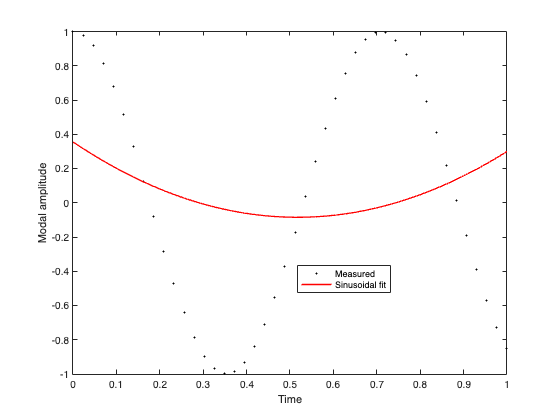

fit = fitModalFrequency(t_pts,a,omega_pred);
 omegaMeas = fit.omega;
 validationError = abs(omegaMeas-omega_pred)/abs(omega_pred);
 measuredDispersion = (omegaMeas-omega_exact)/omega_exact;
 predictedDispersion = (omega_pred-omega_exact)/omega_exact;
 plot(t_pts,a,'k.',t_pts,fit.values,'r-','LineWidth',1.3)
 xlabel('Time'); ylabel('Modal amplitude')
 legend('Measured','Sinusoidal fit','Location','best')

Objects of type `GridFunctionTimeSeries` class method `obj.animate()` for visualizing solutions as grid functions vs x, animated over time.

The `obj.animate()` method is recommended when visualizing the time evolution of the full grid function.

%ax = axes(figure(Name="Pressure")); %This names the figure tab.
%P.animate(FramePause=0.03,Parent=ax);

Here we make use of the `obj.snapshot()` method to visualize a snapshot of the pressure field at the final time, which returns an object of type `GridFunction`. The method `obj.plot()` for `GridFunction` is then used to visualize the pressure field.

% ax = axes(figure(Name="Final pressure"));
% finalPressure = P.snapshot(P.Nt);
% finalPressure.plot(Parent=ax);
% axis image
% title(P.formattedTime(P.Nt));
% ax.YDir="normal"; %This ensures the y-axis has normal orientation

function result = fitModalFrequency(t,a,omegaPred)
 % Fit a(t) = B*cos(omega*t) + C*sin(omega*t) + D.
     t = t(:);
     a = a(:);
     valid = isfinite(t) & isfinite(a);
     t = t(valid);
     a = a(valid);
     % Shift the time origin to improve conditioning.
     tau = t - t(1);
     objective = @(omega) fitResidual(omega,tau,a);
     % A moderate bracket prevents selection of an unrelated minimum.
     omegaLower = 0.8*omegaPred;
     omegaUpper = 1.2*omegaPred;
     options = optimset('TolX',1e-12,'Display','off');
     omegaMeas = fminbnd(objective,omegaLower,omegaUpper,options);
     X = [cos(omegaMeas*tau), ...
          sin(omegaMeas*tau), ...
          ones(size(tau))];
     q = X \ a;
     aFit = X*q;
     B = q(1);
     C = q(2);
     D = q(3);
     result.omega = omegaMeas;
     result.amplitude = hypot(B,C);
     result.phase = atan2(-C,B);
     result.offset = D;
     result.values = aFit;
     result.relResidual = norm(a-aFit)/norm(a);
end
 function value = fitResidual(omega,t,a)
     X = [cos(omega*t), sin(omega*t), ones(size(t))];
     q = X \ a;
     r = a-X*q;
     value = r'*r;
 end